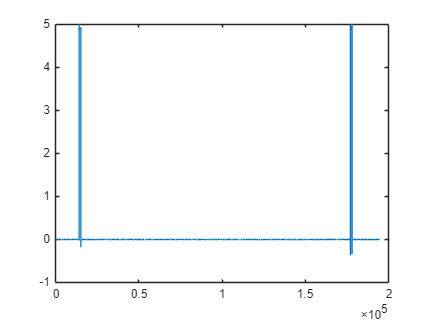


trigger2=Data{1}(:,66);
plot(trigger2);

idx=find(trigger2>1);

mid=1e5;
cut=3.6e5;
startidx=find(idx<mid, 1, 'last' )

startidx = 1021

endidx=find(idx>mid, 1, 'last' )

endidx = 2043

timestart=idx(startidx);
timeend=idx(endidx);
timestart/10240

ans = 1.4717

timeend/10240

ans = 17.3907

all_time=(timeend-timestart)/10240

all_time = 15.9190

data_iemg=double(Data{1}(timestart:timeend,1));
data_semg=double(Data{1}(timestart:timeend,2:65));

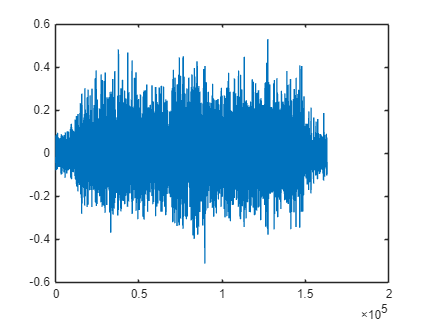

plot(data_iemg)

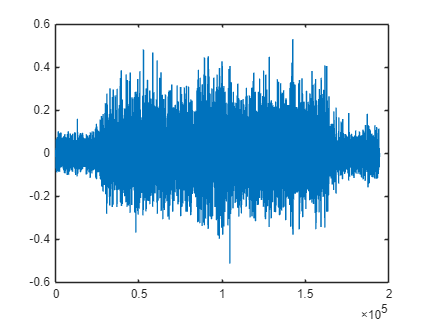

plot(Data{1}(:,1))

% datafinal=int16(data_iemg);
% EMGSIGNAL=datafinal;

% signal=data_iemg;
% Y=fft(signal);
% Fs=10240;L=length(signal);
% P2 = abs(Y/L);
% P1 = P2(1:L/2+1);

% P1(2:end-1) = 2*P1(2:end-1);f = Fs/L*(0:(L/2));
% plot(f,P1,"LineWidth",1) 
% title("单边频谱M1L1T4#17-最终滤波后")
% xlabel("f (Hz)")
% ylabel("|P1(f)|")